# **Adding compensation for radial distortion**

Use already implemented Zhang procedure to obtain an estimation of camera parameters for each image we have at our disposal.

% load checkerboard images and 
% obtain results of Zhang procedure
clear imageData
folder = 'images';
data = zhangMethod(folder, [12,13]); % call the script which implements Zhang procedure

Data loaded and points detected 
Checking the number of keypoints... 
Estimating camera parameters for each image... 
Everythin done. 


n = length(data); % number of images

As we have already seen, if we perform projection using the obtain projection matrix, we get a significant error.

Let's see it clearly on the first image. We measure the reprojection error as the distance between the estimated and the measured projections.

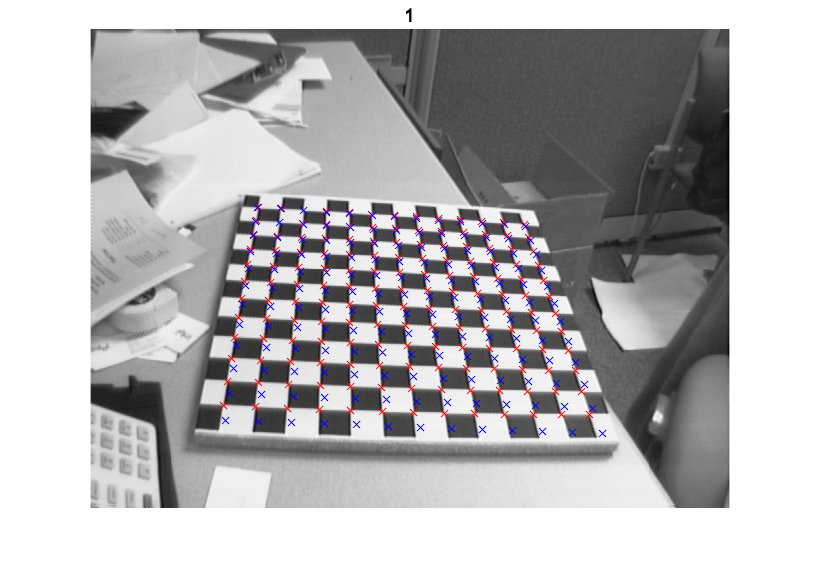

idx = 1; % choose first image
XYpixel = data(idx).XYpixel;
XYmm = data(idx).XYmm;

error = 0;

figure
imshow(data(idx).I, 'initialmagnification',200);
title(num2str(idx))
hold on

for i=1:length(XYpixel)

    % coordinates of point in mm
    Xpixel=XYpixel(i,1); % u
    Ypixel=XYpixel(i,2); % v
    Xmm=XYmm(i,1);  % x
    Ymm=XYmm(i,2); % y

    m = [Xmm; Ymm; 0; 1];
            
    P = data(idx).P;

    estimated_u =  (P(1,:)*m)/(P(3,:)*m);
    estimated_v = (P(2,:)*m)/(P(3,:)*m);
    eu = estimated_u - Xpixel; % error on u
    ev = estimated_v - Ypixel; % error on v

    error = error + sqrt(eu^2 + ev^2);

    scatter(Xpixel,Ypixel, 'x', 'r');
    scatter(estimated_u,estimated_v, 'x', 'b');
end

fprintf("Obtained reprojection error is: %d pixels", error);

Obtained reprojection error is: 1.200882e+03 pixels

Compute the reprojection error for each image and save it in data structure.

for i=1:n
    error = 0;
    XYpixel = data(i).XYpixel;
    XYmm = data(i).XYmm;

    for j=1:length(XYpixel)
        % coordinates of point in mm
        Xpixel=XYpixel(j,1); % u
        Ypixel=XYpixel(j,2); % v
        Xmm=XYmm(j,1);  % x
        Ymm=XYmm(j,2); % y
    
        m = [Xmm; Ymm; 0; 1];
                
        P = data(i).P;
    
        estimated_u =  (P(1,:)*m)/(P(3,:)*m);
        estimated_v = (P(2,:)*m)/(P(3,:)*m);
        eu = estimated_u - Xpixel; % error on u
        ev = estimated_v - Ypixel; % error on v
    
        error = error + sqrt(eu^2 + ev^2);
    end
    data(i).error = error;
end

Now we apply the procedure for radial distortion compensation in order to obtain a new estimation of P for each image and, most importantly, the radial distortion parameters $k1$ and $k2$, which are needed for the representation of undistorted image.

[new_data, k] = radialDistortionCompensation(data);

lsqr converged at iteration 2 to a solution with relative residual 0.97.
lsqr converged at iteration 2 to a solution with relative residual 0.87.
lsqr converged at iteration 2 to a solution with relative residual 0.72.
lsqr converged at iteration 2 to a solution with relative residual 0.57.
lsqr converged at iteration 2 to a solution with relative residual 0.45.
lsqr converged at iteration 2 to a solution with relative residual 0.38.
lsqr converged at iteration 2 to a solution with relative residual 0.33.
lsqr converged at iteration 2 to a solution with relative residual 0.3.
lsqr converged at iteration 2 to a solution with relative residual 0.29.
lsqr converged at iteration 2 to a solution with relative residual 0.29.
lsqr converged at iteration 2 to a solution with relative residual 0.29.
lsqr converged at iteration 2 to a solution with relative residual 0.29.
lsqr converged at iteration 2 to a solution with relative residual 0.29.
lsqr converged at iteration 2 to a solution with rel

k1 = k(1); k2 = k(2);

Now we have a new estimation of P for each image and we can compute the undistorted projection of our points.

Of course to see what is happening we also have to plot the undistorted representation of our image.

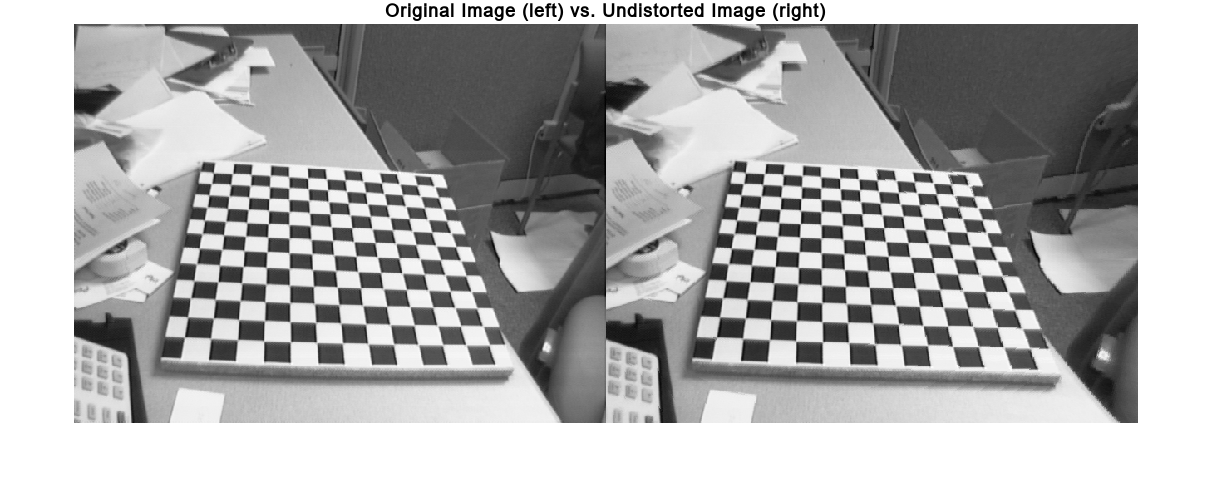

% compute undistorted representation for image 1 and plot it beside the
% distorted one

idx = 1;
original_img = data(idx).I;
undistorted_img = original_img;

K = data(idx).K;
u0 = K(1,3);
v0 = K(2,3);
alpha_u = K(1,1);
theta = acot(K(1,2)/alpha_u); % skew angle between u and v axes, the angle is measured in radians
alpha_v = K(2,2)*sin(theta);

for u=1:size(original_img,1)
    for v=1:size(original_img,2)
        % find the distorted corresponding coordinates of (u,v)
        rd = ((u-u0)/alpha_u)^2 + ((v-v0)/alpha_v)^2;
        uhat = (u - u0)*(1+ k1*rd + k2*rd^2) + u0;
        vhat = (v - v0)*(1+ k1*rd + k2*rd^2) + v0;
        
        % image undistortion algorithm can produce noninteger values of (u,v)
        % for this reason interpolation is needed
        % find the four neighboring pixels and the distance from the
        % top-left one wrt to u and v axes
        p1 = [floor(uhat); floor(vhat)]; % top left pixel
        p2 = [ceil(uhat); floor(vhat)]; % top right pixel
        p3 = [floor(uhat); ceil(vhat)]; % bottom left pixel
        p4 = [ceil(uhat); ceil(vhat)]; % bottom right pixel
        
        delta_u = (uhat - p1(1));
        delta_v = (vhat - p1(2));
        out_pixel = p1*(1 - delta_u)*(1-delta_v) + p2*delta_u*(1-delta_v) + p3*(1-delta_u)*delta_v + p4*delta_u*delta_v;
      
        % the intensity of I(u,v) in the undistorted image is the one of
        % (uhat, vhat) in the distorted image
        undistorted_img(u, v) = data(idx).I(round(out_pixel(1)),round(out_pixel(2)));
    end
end

% plot the two images one beside the other
figure; 
imshowpair(original_img,undistorted_img,'montage');
title('Original Image (left) vs. Undistorted Image (right)');

Now we show on distorted image the representation of checkerboard points and their projections obtained by using the newly estimated projection matrix P.

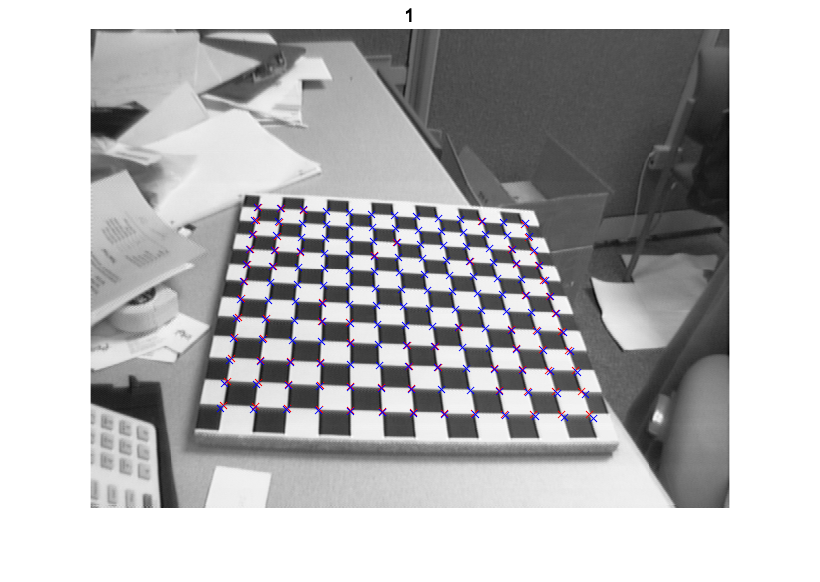

idx = 1; % choose first image
XYpixel = new_data(idx).XYpixel;
XYmm = new_data(idx).XYmm;

error = 0;

figure
imshow(original_img, 'initialmagnification',200);
title(num2str(idx))
hold on

for i=1:length(XYpixel)

    % coordinates of point in mm
    Xpixel=XYpixel(i,1); % u
    Ypixel=XYpixel(i,2); % v
    Xmm=XYmm(i,1);  % x
    Ymm=XYmm(i,2); % y

    m = [Xmm; Ymm; 0; 1];
            
    P = new_data(idx).P;

    estimated_u =  (P(1,:)*m)/(P(3,:)*m);
    estimated_v = (P(2,:)*m)/(P(3,:)*m);
    eu = estimated_u - Xpixel; % error on u
    ev = estimated_v - Ypixel; % error on v

    error = error + sqrt(eu^2 + ev^2);

    scatter(Xpixel,Ypixel, 'x', 'r');
    scatter(estimated_u,estimated_v, 'x', 'b');
end

fprintf("Obtained reprojection error is: %d pixels", error);

Obtained reprojection error is: 1.135150e+02 pixels

Finally, we comput again the reprojection error for each image and we compare them with the previous ones.

for i=1:n
    error = 0;
    XYpixel = data(i).XYpixel;
    XYmm = data(i).XYmm;

    for j=1:length(XYpixel)
        % coordinates of point in mm
        Xpixel=XYpixel(j,1); % u
        Ypixel=XYpixel(j,2); % v
        Xmm=XYmm(j,1);  % x
        Ymm=XYmm(j,2); % y
    
        m = [Xmm; Ymm; 0; 1];
                
        P = new_data(i).P;
    
        estimated_u =  (P(1,:)*m)/(P(3,:)*m);
        estimated_v = (P(2,:)*m)/(P(3,:)*m);
        eu = estimated_u - Xpixel; % error on u
        ev = estimated_v - Ypixel; % error on v
    
        error = error + sqrt(eu^2 + ev^2);
    end
    new_data(i).error = error;
end

e1 = zeros(n,1); e2 = zeros(n,1);
for i=1:n 
    e1(i) = data(i).error; 
    e2(i) = new_data(i).error; 
end
varNames = {'error before compensation', 'error after compensation'};
table(e1, e2, 'VariableNames',varNames)

ans = 20×2 table
    error before compensation    error after compensation
    _________________________    ________________________

             1200.9                       113.52         
             697.46                       406.11         
             466.84                       324.76         
             397.92                       266.12         
             435.18                       256.07         
             557.17                       340.49         
             301.42                       476.02         
             1066.7                       532.72         
             994.88                       351.56         
              267.6                       338.71         
             682.82                       344.86         
             1001.5                       203.29         
                521                       230.31         
             893.25                       21

Provide a visualization of previous results for each image, saving the comparison between the originl and the undistorted one in 'radial_compensation' folder.

lsqr converged at iteration 2 to a solution with relative residual 0.98.


k1 = -0.0490

k2 = -0.1766

ans =     0.1192
   -1.1289


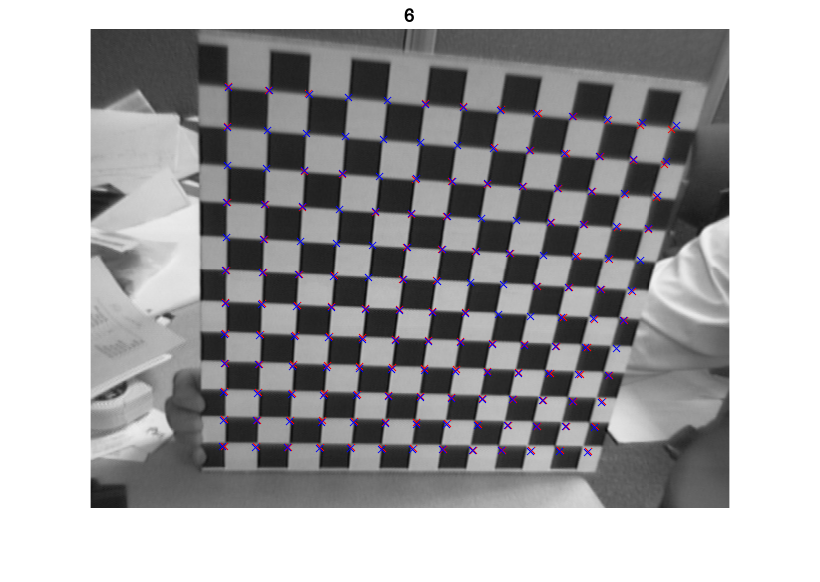

folder = 'radial_compensation';

for idx=1:n 
    figure('visible','off');
 
    original_img = data(idx).I;
    undistorted_img = original_img;

    K = new_data(idx).K;
    u0 = K(1,3);
    v0 = K(2,3);
    alpha_u = K(1,1);
    theta = acot(K(1,2)/alpha_u); % skew angle between u and v axes, the angle is measured in radians
    alpha_v = K(2,2);%*sin(theta);

    for u=1:size(I,1)
        for v=1:size(I,2)
            % find the distorted corresponding coordinates of (u,v)
            rd = ((u-u0)/alpha_u)^2 + ((v-v0)/alpha_v)^2;
            uhat = (u - u0)*(1+ k1*rd + k2*rd^2) + u0;
            vhat = (v - v0)*(1+ k1*rd + k2*rd^2) + v0;
            
            % image undistortion algorithm can produce noninteger values of (u,v)
            % for this reason interpolation is needed
            % find the four neighboring pixels and the distance from the
            % top-left one wrt to u and v axes
            p1 = [floor(uhat); floor(vhat)]; % top left pixel
            p2 = [ceil(uhat); floor(vhat)]; % top right pixel
            p3 = [floor(uhat); ceil(vhat)]; % bottom left pixel
            p4 = [ceil(uhat); ceil(vhat)]; % bottom right pixel
            
            delta_u = (uhat - p1(1));
            delta_v = (vhat - p1(2));
            out_pixel = p1*(1 - delta_u)*(1-delta_v) + p2*delta_u*(1-delta_v) + p3*(1-delta_u)*delta_v + p4*delta_u*delta_v;
          
            % the intensity of I(u,v) in the undistorted image is the one of
            % (uhat, vhat) in the distorted image
            undistorted_img(u, v) = data(idx).I(round(out_pixel(1)),round(out_pixel(2)));
        end
    end

   
    img = imshowpair(original_img,undistorted_img,'montage');
    title('Original Image (left) vs. Undistorted Image (right)');
    
    file_name = sprintf('Image%d.png', idx); % name Image with a sequence of number, ex Image1.png , Image2.png....
    fullFileName = fullfile(folder, file_name);
    saveas(img,fullFileName,'png'); %save the image 

 end    

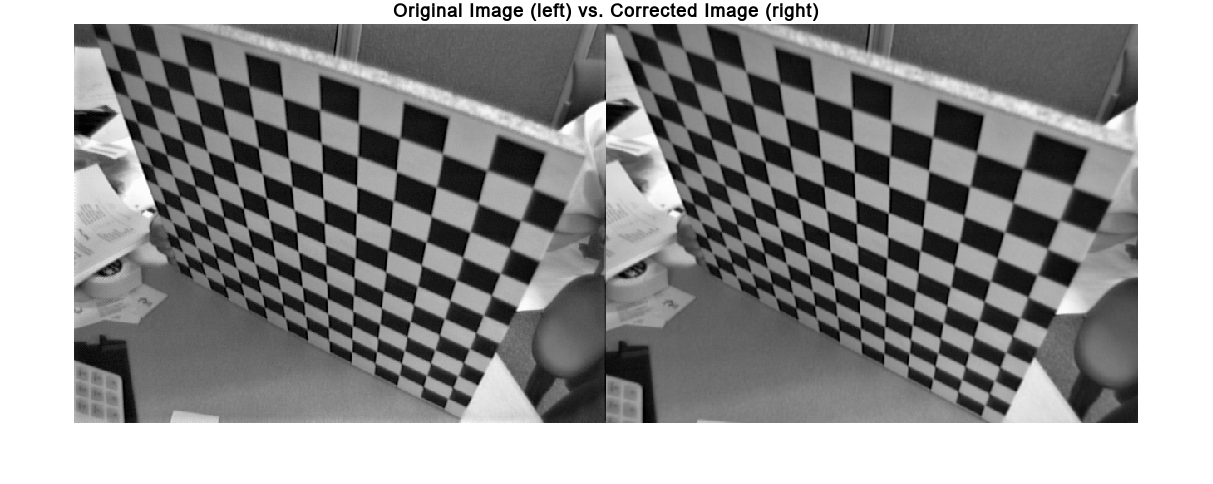

images = imageDatastore(fullfile('images'), "FileExtensions",[".jpg",".tif"]);
[imagePoints,boardSize] = detectCheckerboardPoints(images.Files,'PartialDetections', false);

squareSize = 30;
worldPoints = generateCheckerboardPoints(boardSize,squareSize);

idx = 10;
I = readimage(images,idx); 
imageSize = [size(I,1),size(I,2)];
cameraParams = estimateCameraParameters(imagePoints,worldPoints, ...
                                  'ImageSize',imageSize);

I = images.readimage(idx);
J1 = undistortImage(I,cameraParams);
figure; imshowpair(I,J1,'montage');
title('Original Image (left) vs. Corrected Image (right)'); 

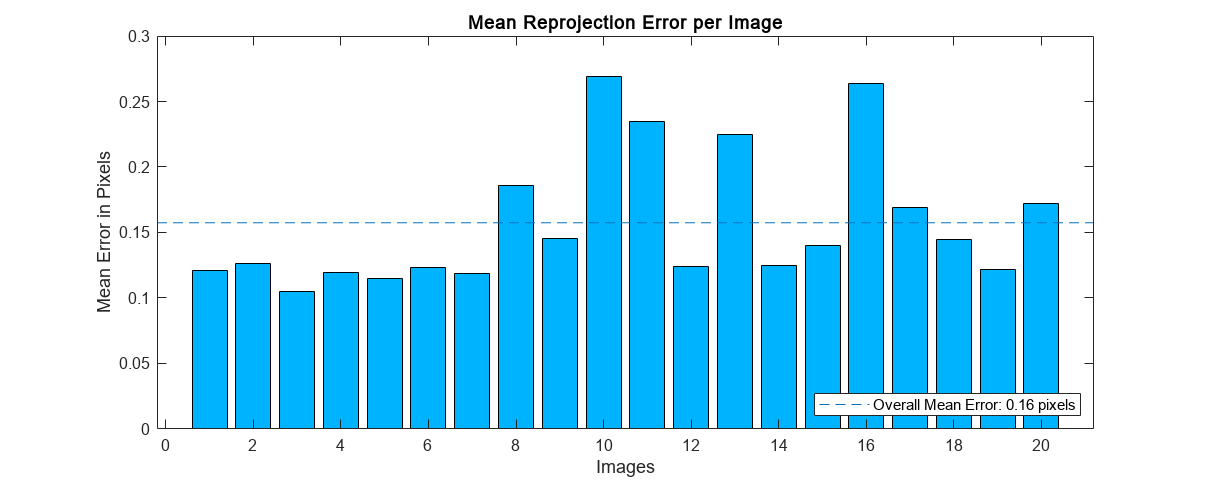

showReprojectionErrors(cameraParams)